Hello testing

[A, b, x]  = LOC_G_BLK_A_INTERNAL()

$$A = \left(\begin{array}{ccccccccc} 0 & -\frac{\Delta_{X}\,k_{A}}{\Delta_{Y}} & 0 & -\frac{\Delta_{Y}\,k_{A}}{\Delta_{X}} & \frac{2\,\Delta_{X}\,k_{A}}{\Delta_{Y}}+\frac{2\,\Delta_{Y}\,k_{A}}{\Delta_{X}} & -\frac{\Delta_{Y}\,k_{A}}{\Delta_{X}} & 0 & -\frac{\Delta_{X}\,k_{A}}{\Delta_{Y}} & 0 \end{array}\right)$$

$$b = \left(\begin{array}{c} 0 \end{array}\right)$$

$$x = \left(\begin{array}{ccccccccc} T_{\mathrm{mM1},\mathrm{nP1}} & T_{m,\mathrm{nP1}} & T_{\mathrm{mP1},\mathrm{nP1}} & T_{\mathrm{mM1},n} & T_{m,n} & T_{\mathrm{mP1},n} & T_{\mathrm{mM1},\mathrm{nM1}} & T_{m,\mathrm{nM1}} & T_{\mathrm{mP1},\mathrm{nM1}} \end{array}\right)$$

hello

# Local Subfunctions only beyond this point

# **B-block**

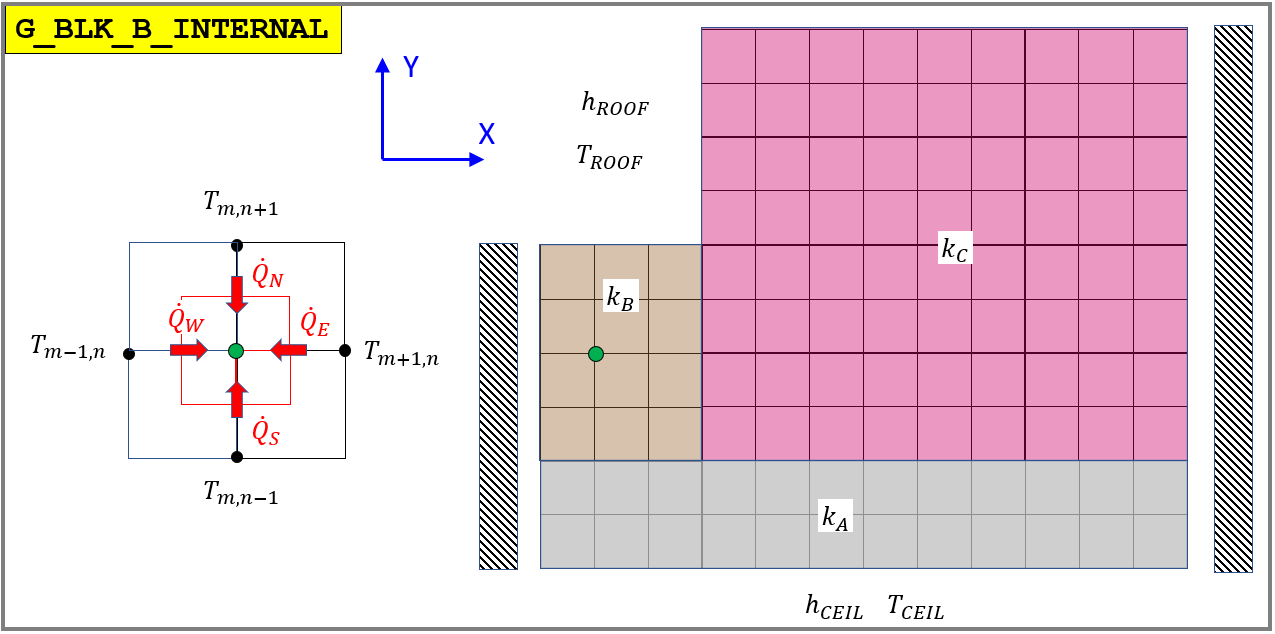

function [A, b, x]  = LOC_G_BLK_B_INTERNAL()
  %Load symbolic symbols
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N , A_S , A_E , A_W ] = LOC_get_A_NSEW("N_FULL", "S_FULL", "E_FULL", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_B ,     k_B,      k_B,      k_B);
  
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

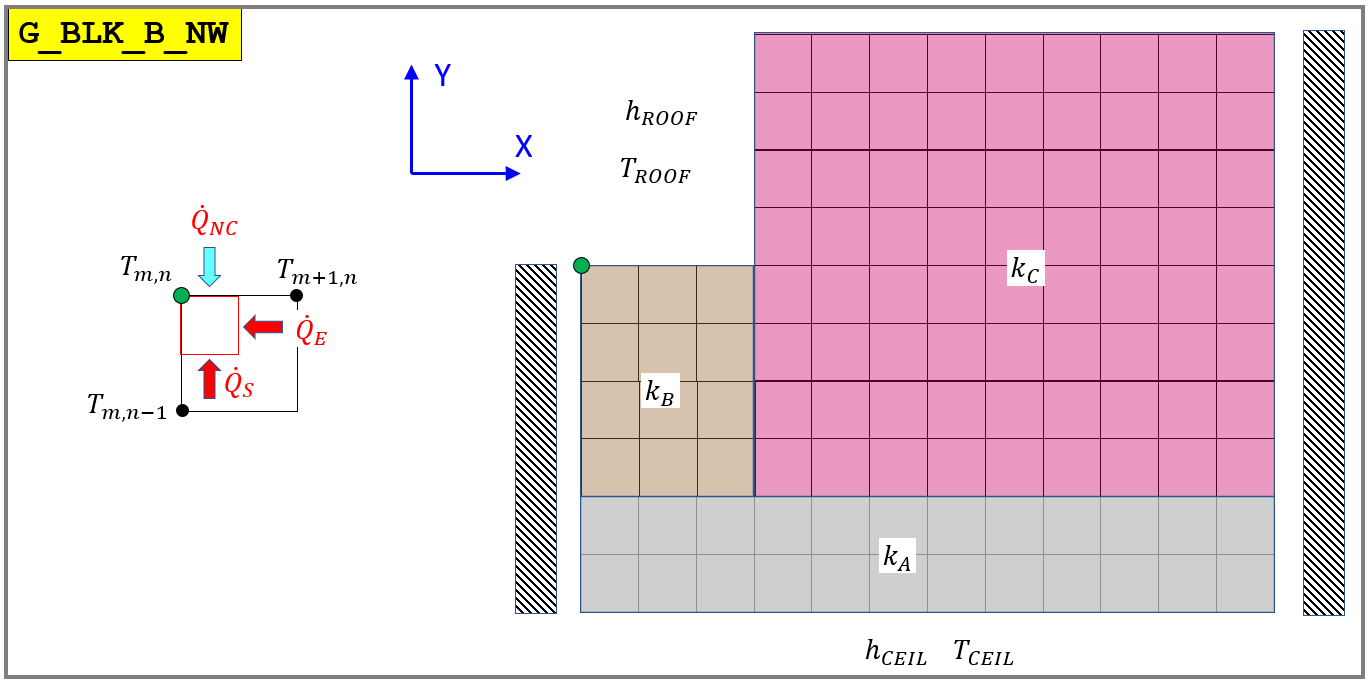

function [A, b, x]  = LOC_G_BLK_B_NW()
  %Load symbolic symbols
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_HALF", "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N , A_S , A_E , A_W ] = LOC_get_A_NSEW("N_0"   , "S_HALF", "E_HALF", "W_0"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( sym(0) ,   k_B,      k_B,    sym(0));
  
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

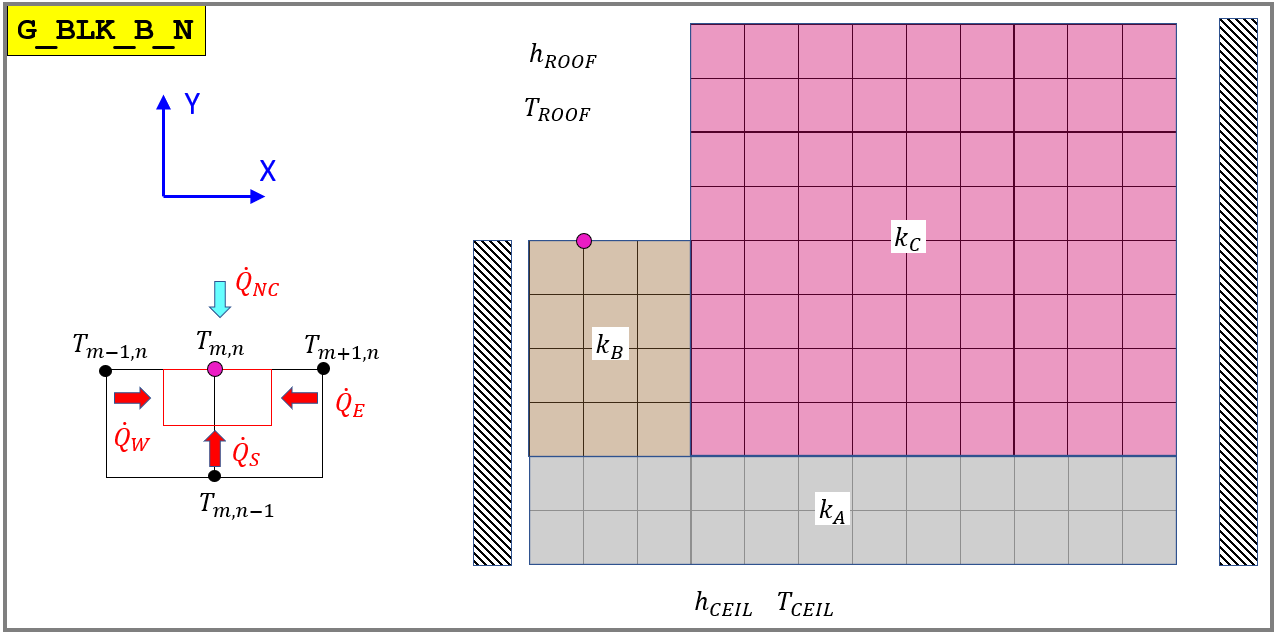

function [A, b, x]  = LOC_G_BLK_B_N()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_FULL", "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_0"   , "S_FULL", "E_HALF", "W_HALF"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( sym(0),    k_B,      k_B,      k_B);
  
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

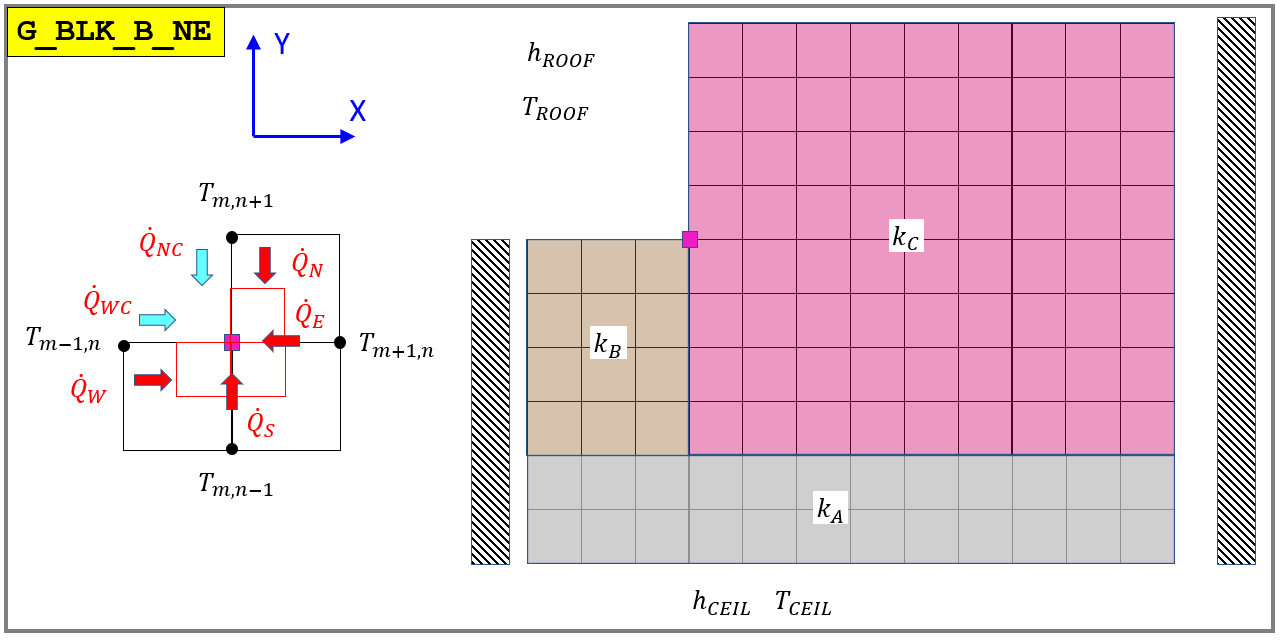

function [A, b, x]  = LOC_G_BLK_B_NE()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_HALF", "S_0"   , "E_0"   , "W_HALF"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF", "S_FULL", "E_FULL", "W_HALF"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_C,      k_C,      k_C,      k_B);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

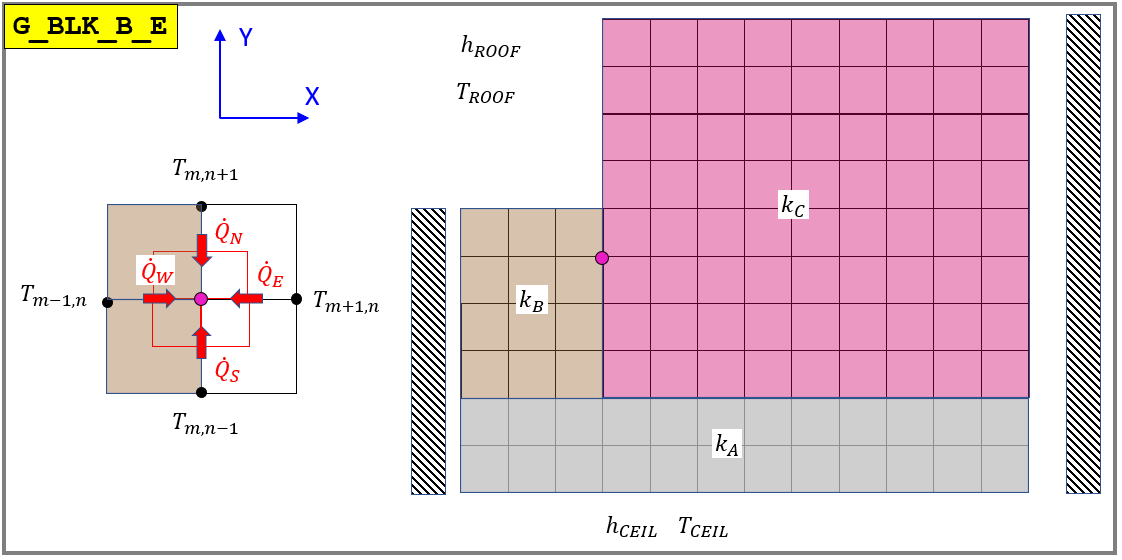

function [A, b, x]  = LOC_G_BLK_B_E()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_FULL", "S_FULL", "E_FULL", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_C,      k_C,      k_C,      k_B);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

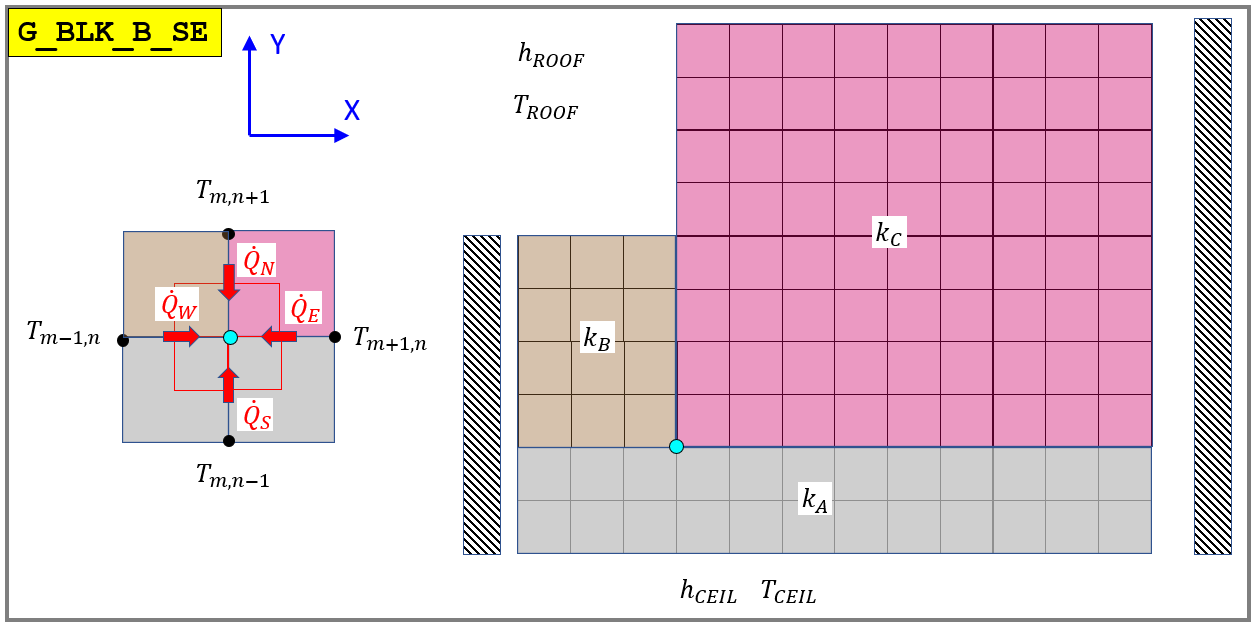

function [A, b, x]  = LOC_G_BLK_B_SE()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_FULL", "S_FULL", "E_FULL", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_C,      k_A,      k_C,      k_B);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

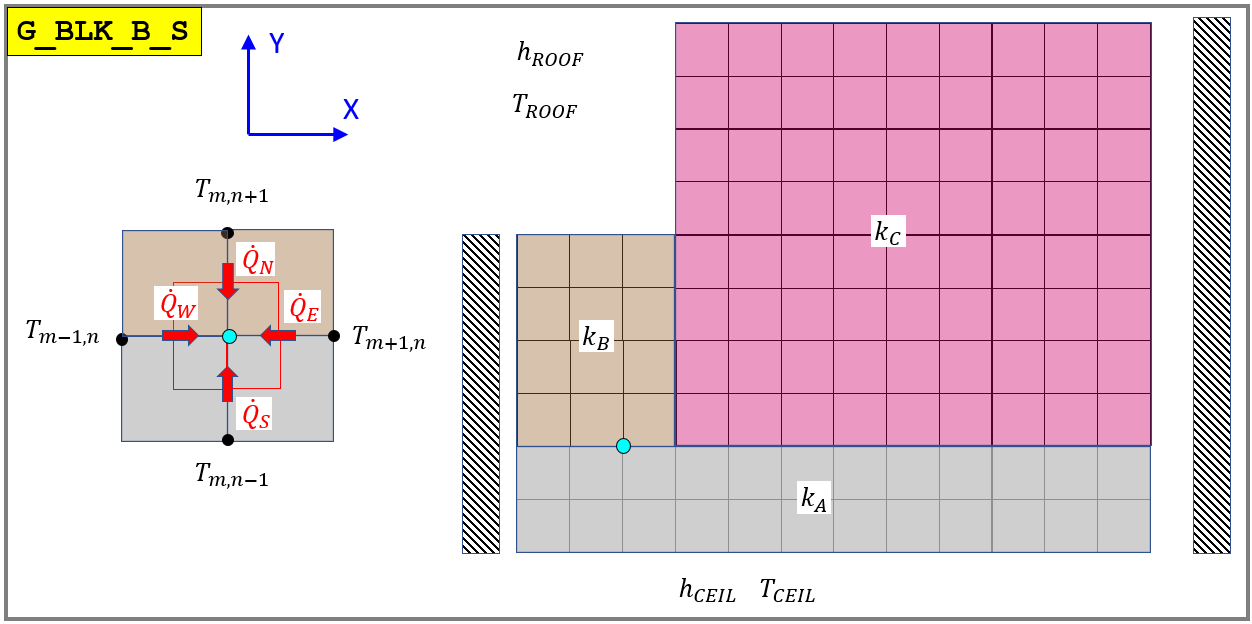

function [A, b, x]  = LOC_G_BLK_B_S()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_FULL", "S_FULL", "E_FULL", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_B,      k_A,      k_B,      k_B);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

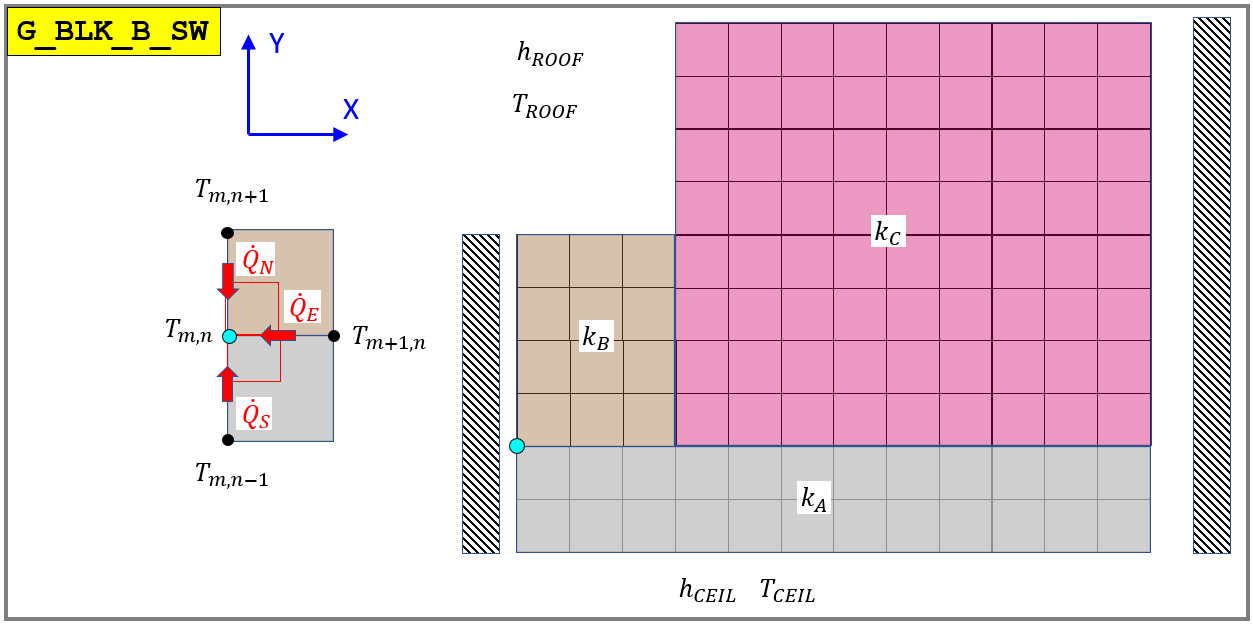

function [A, b, x]  = LOC_G_BLK_B_SW()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF", "S_HALF", "E_FULL", "W_0"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_B,      k_A,      k_B,     sym(0));
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

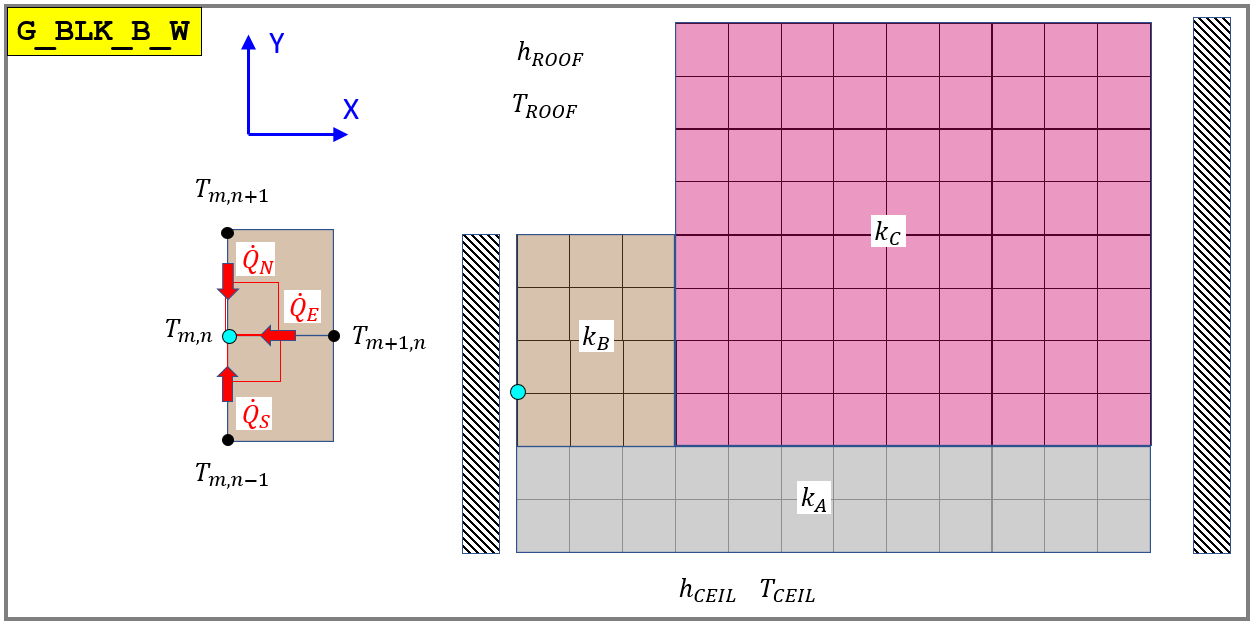

function [A, b, x]  = LOC_G_BLK_B_W()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF", "S_HALF", "E_FULL", "W_0"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_B,      k_B,      k_B,     sym(0));
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

# **C-block**

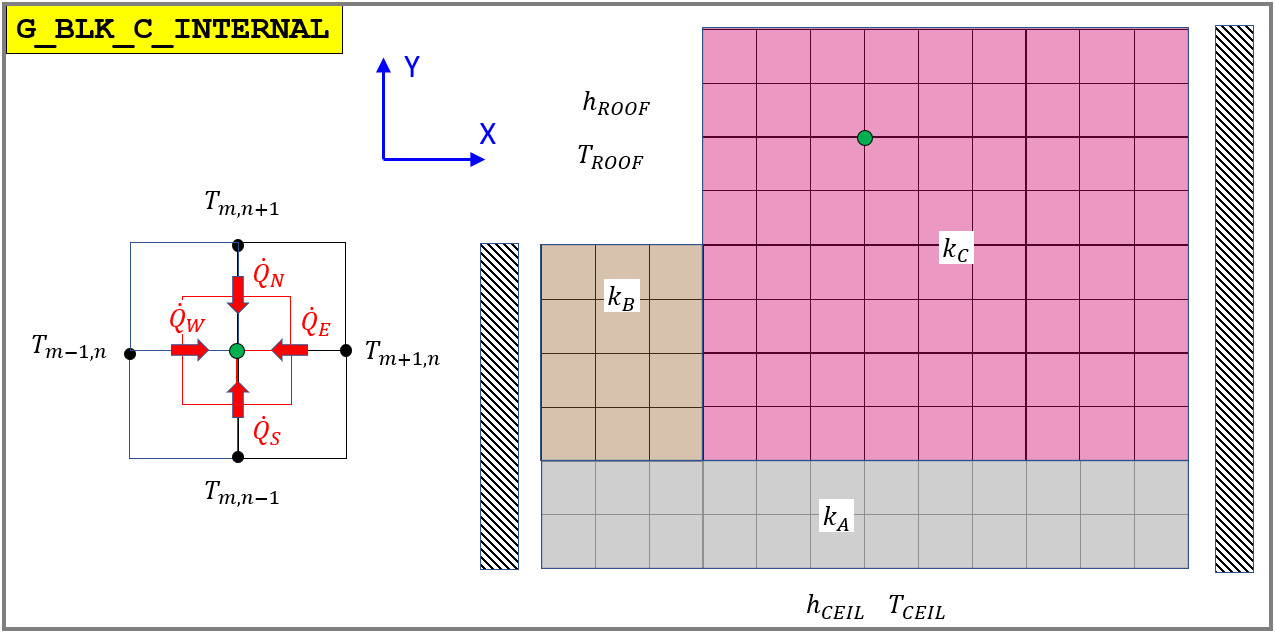

function [A, b, x]  = LOC_G_BLK_C_INTERNAL()
  %Load symbolic symbols
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N , A_S , A_E , A_W ] = LOC_get_A_NSEW("N_FULL", "S_FULL", "E_FULL", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_C ,     k_C,      k_C,      k_C);
  
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

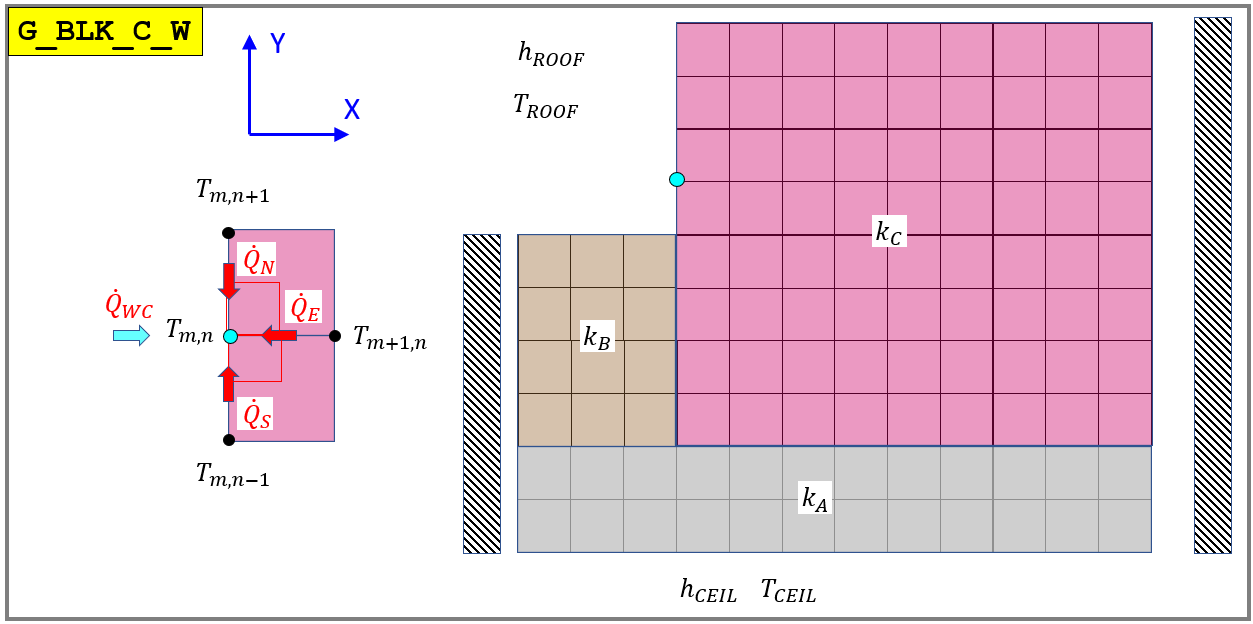

function [A, b, x]  = LOC_G_BLK_C_W()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_FULL"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF", "S_HALF", "E_FULL", "W_0"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_C,      k_C,      k_C,     sym(0));
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

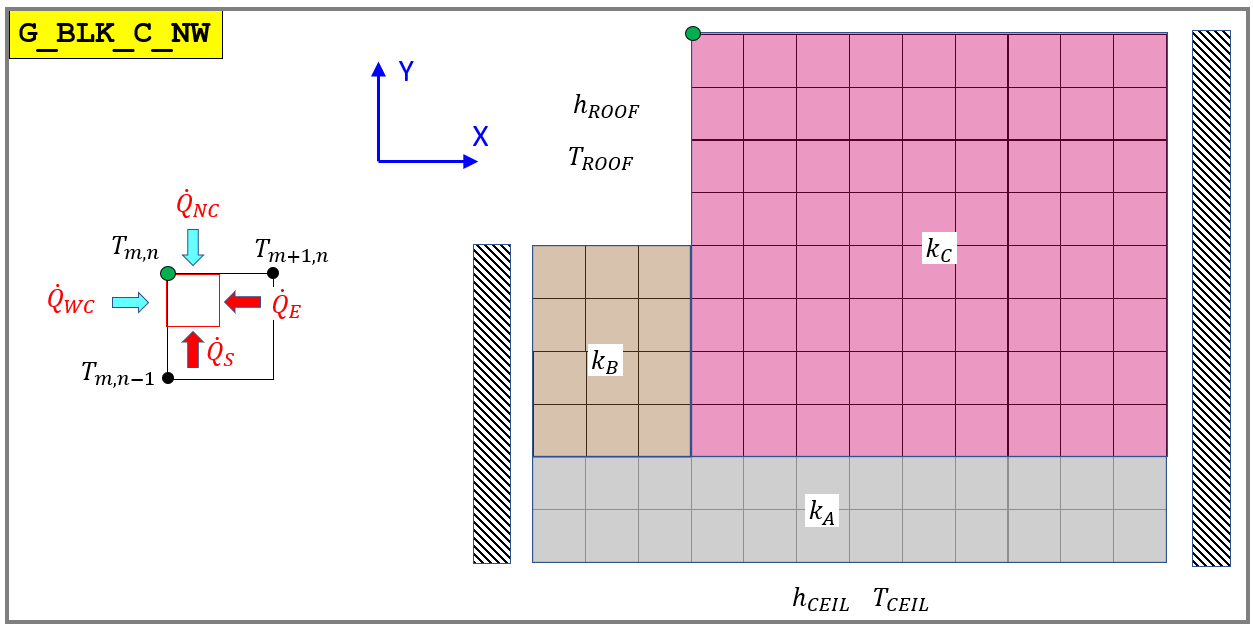

function [A, b, x]  = LOC_G_BLK_C_NW()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_HALF",  "S_0"   , "E_0"   , "W_HALF"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_0",     "S_HALF", "E_HALF", "W_0"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( sym(0),    k_C,      k_C,     sym(0));
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

# 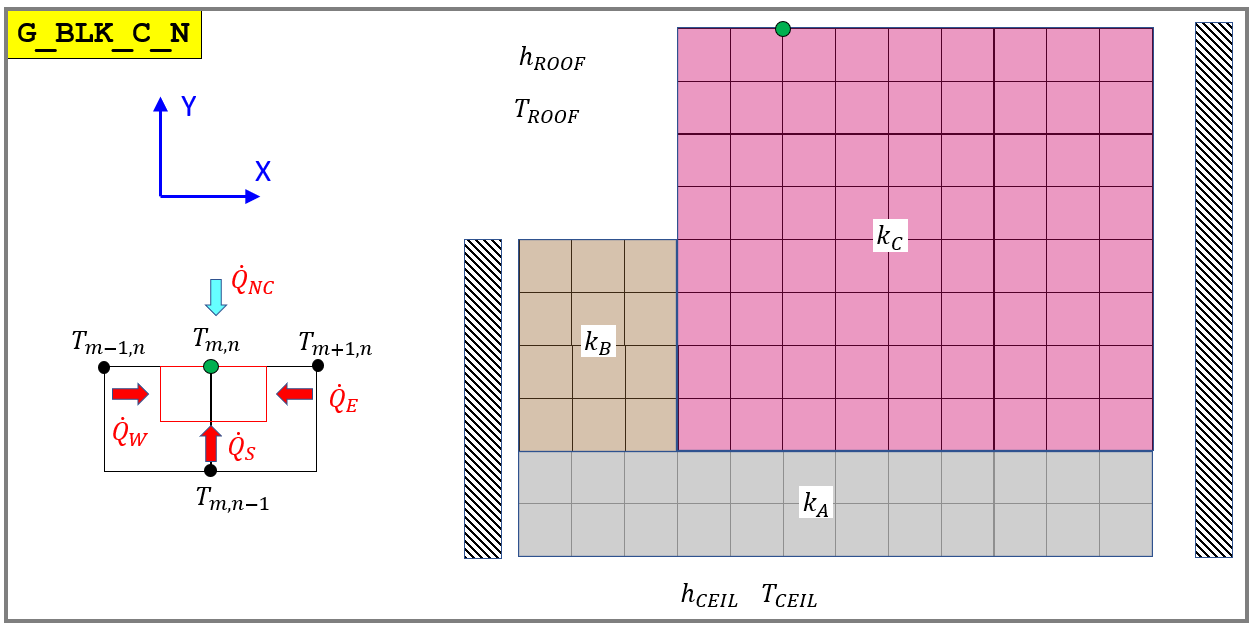

function [A, b, x]  = LOC_G_BLK_C_N()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_FULL",  "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_0",     "S_FULL", "E_HALF", "W_HALF"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( sym(0),    k_C,      k_C,     k_C);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

# 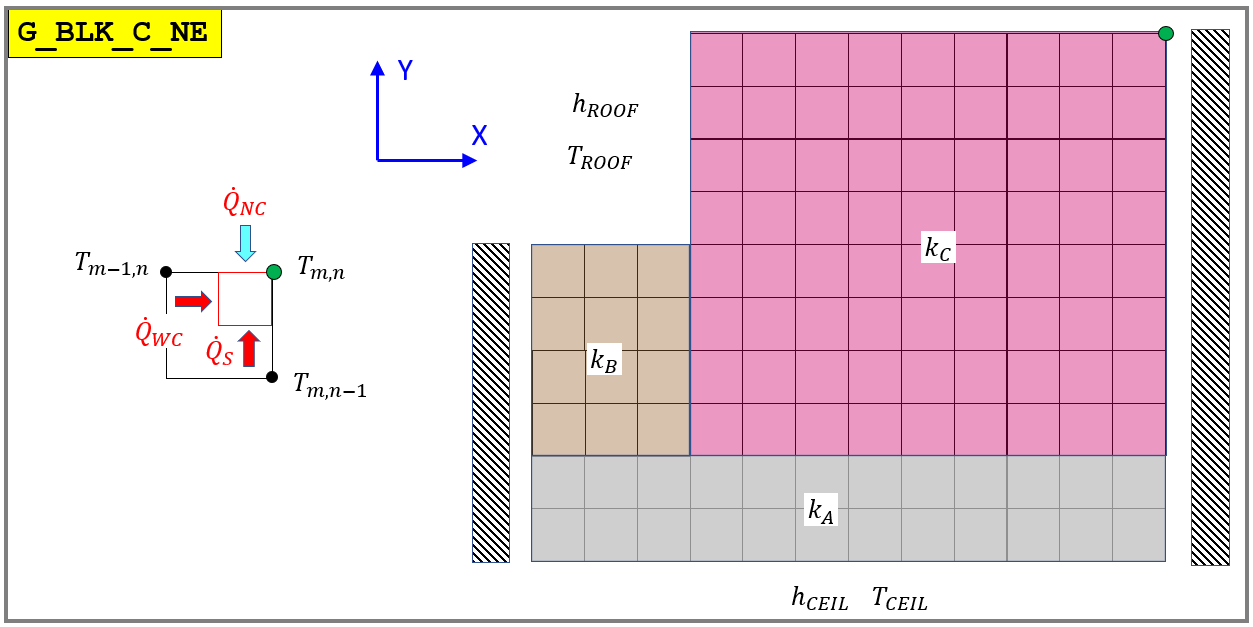

function [A, b, x]  = LOC_G_BLK_C_NE()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_HALF",  "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_0",     "S_HALF", "E_0", "W_HALF"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( sym(0),    k_C,    sym(0),    k_C);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

# 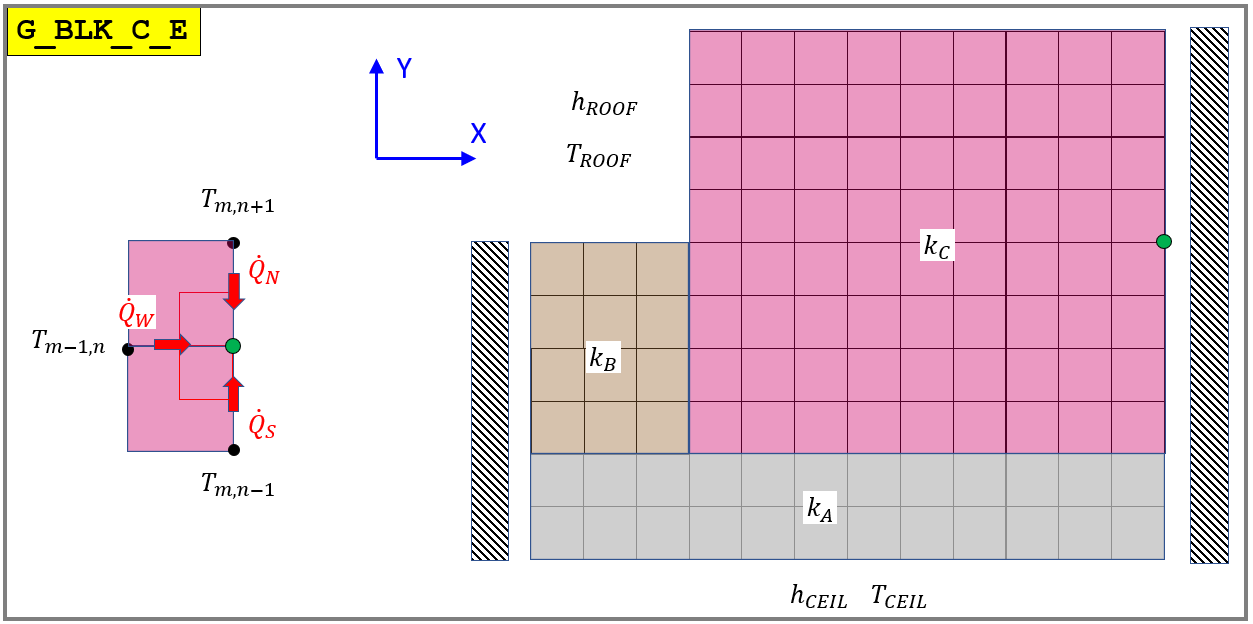

function [A, b, x]  = LOC_G_BLK_C_E()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",     "S_0"   , "E_0", "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF",  "S_HALF", "E_0", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_C,       k_C,    sym(0),    k_C);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

# 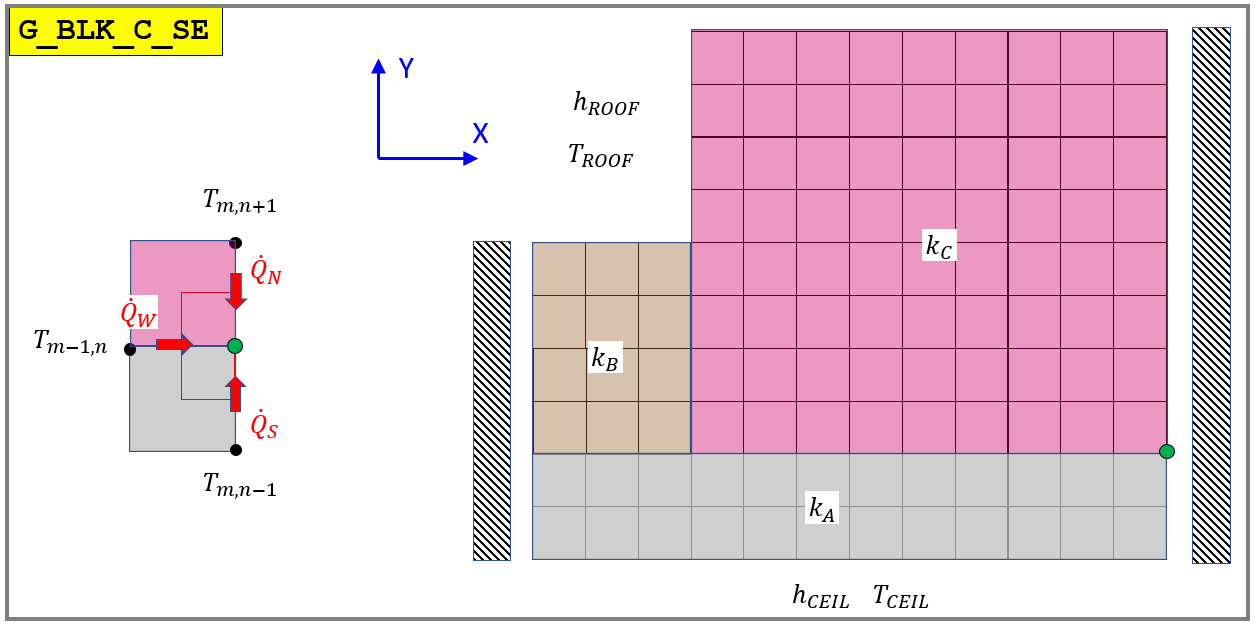

function [A, b, x]  = LOC_G_BLK_C_SE()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",     "S_0"   , "E_0", "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF",  "S_HALF", "E_0", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_C,       k_A,    sym(0),    k_C);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

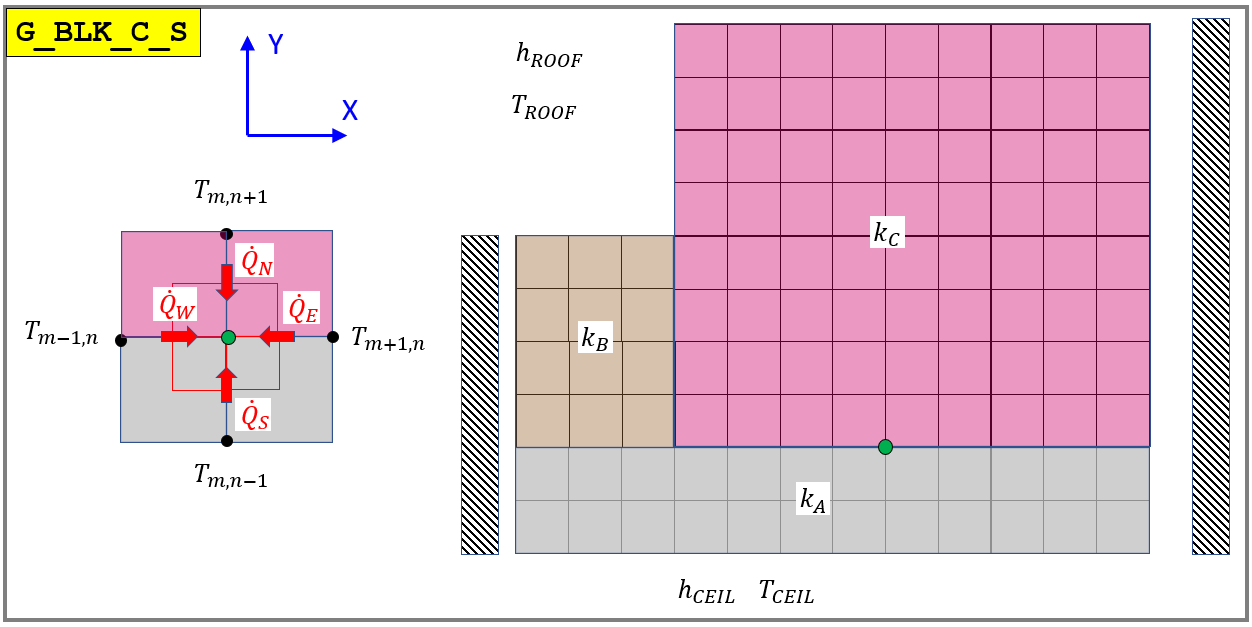

function [A, b, x]  = LOC_G_BLK_C_S()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",     "S_0"   , "E_0",    "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_FULL",  "S_FULL", "E_FULL", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_C,       k_A,      k_C,    k_C);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d);    
end
%%%
%%
%

# **A-block**

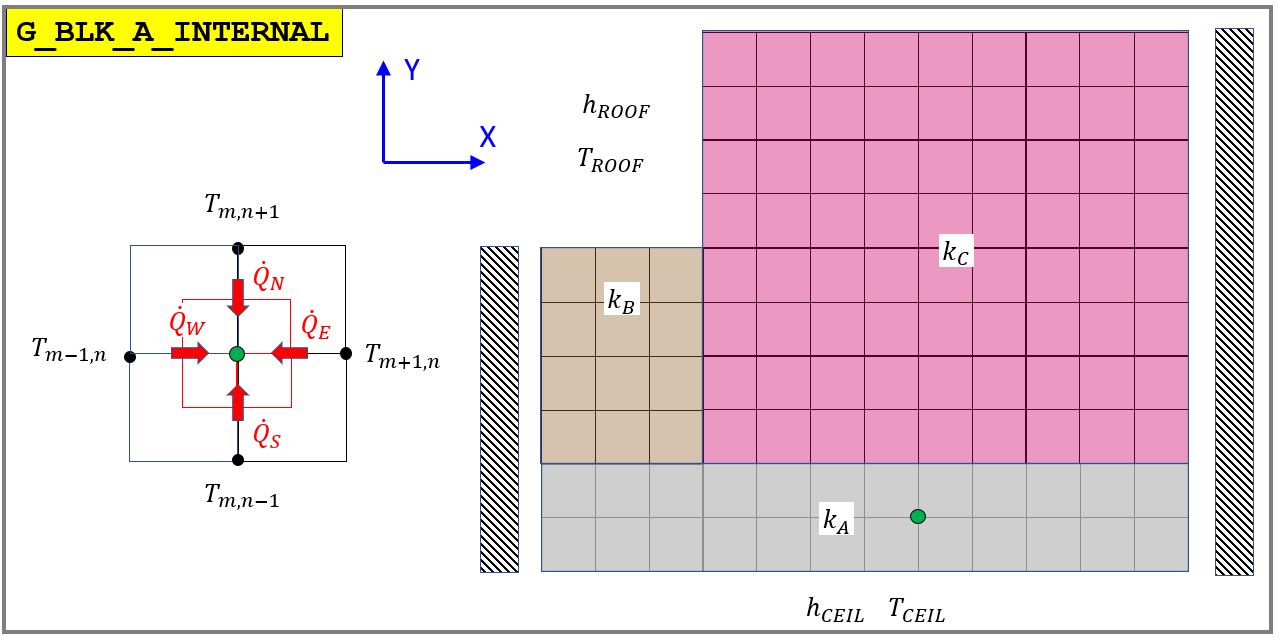

function [A, b, x]  = LOC_G_BLK_A_INTERNAL()
  %Load symbolic symbols
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N , A_S , A_E , A_W ] = LOC_get_A_NSEW("N_FULL", "S_FULL", "E_FULL", "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_A ,     k_A,      k_A,      k_A);
  
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc_BLK_A(A_cond, A_conv, k, d);    
end
%%%
%%
%

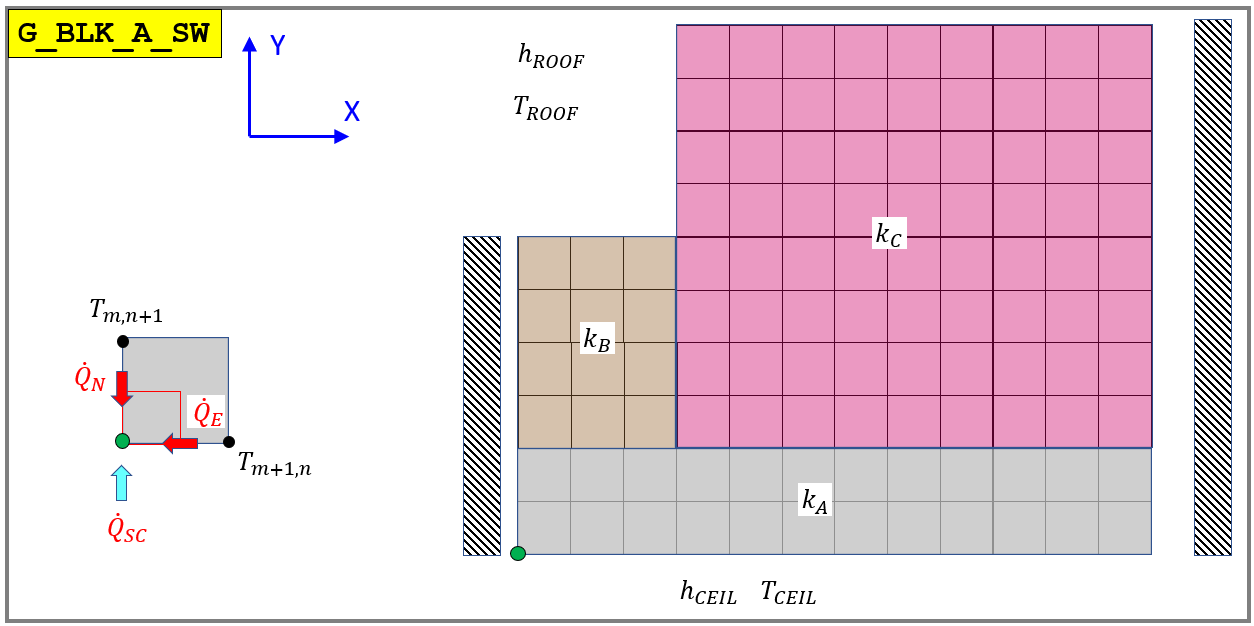

function [A, b, x]  = LOC_G_BLK_A_SW()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",     "S_HALF", "E_0",    "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF",  "S_0",    "E_HALF", "W_0"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_A,       sym(0),   k_A,    sym(0));
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc_BLK_A(A_cond, A_conv, k, d);    
end
%%%
%%
%

# 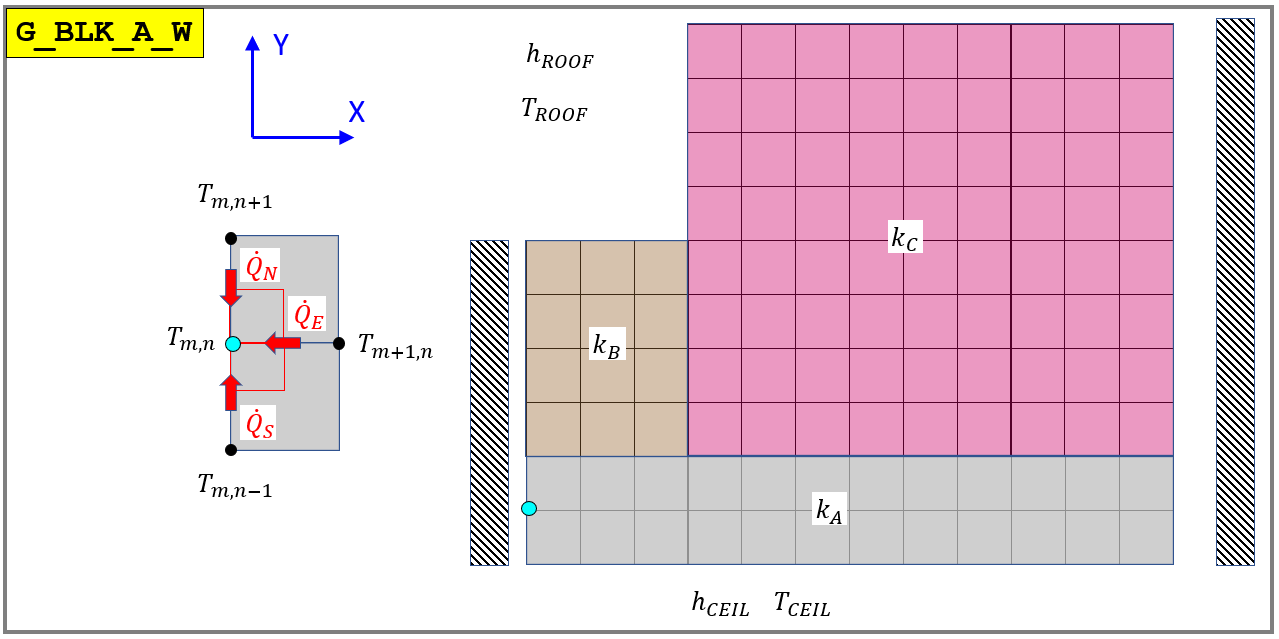

function [A, b, x]  = LOC_G_BLK_A_W()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0"   , "E_0"   , "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF", "S_HALF", "E_FULL", "W_0"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_A,      k_A,      k_A,     sym(0));
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc_BLK_A(A_cond, A_conv, k, d);    
end
%%%
%%
%

# 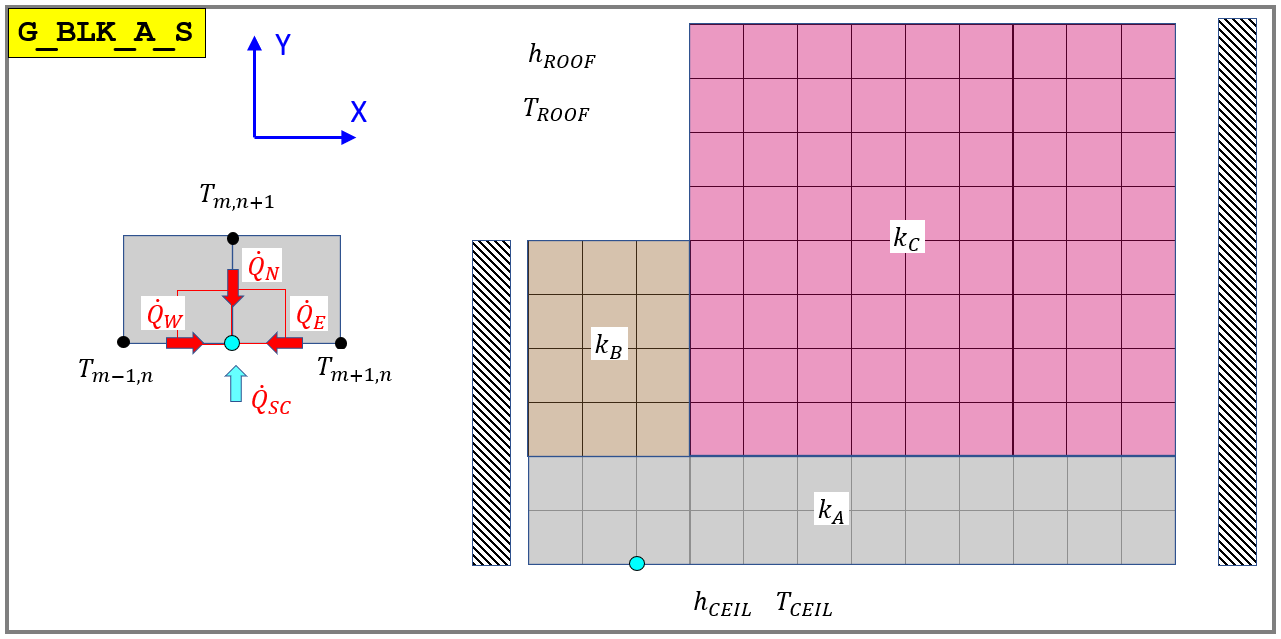

function [A, b, x]  = LOC_G_BLK_A_S()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_FULL",  "E_0",    "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_FULL", "S_0",     "E_HALF", "W_HALF"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_A,      sym(0),     k_A,     k_A);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc_BLK_A(A_cond, A_conv, k, d);    
end
%%%
%%
%

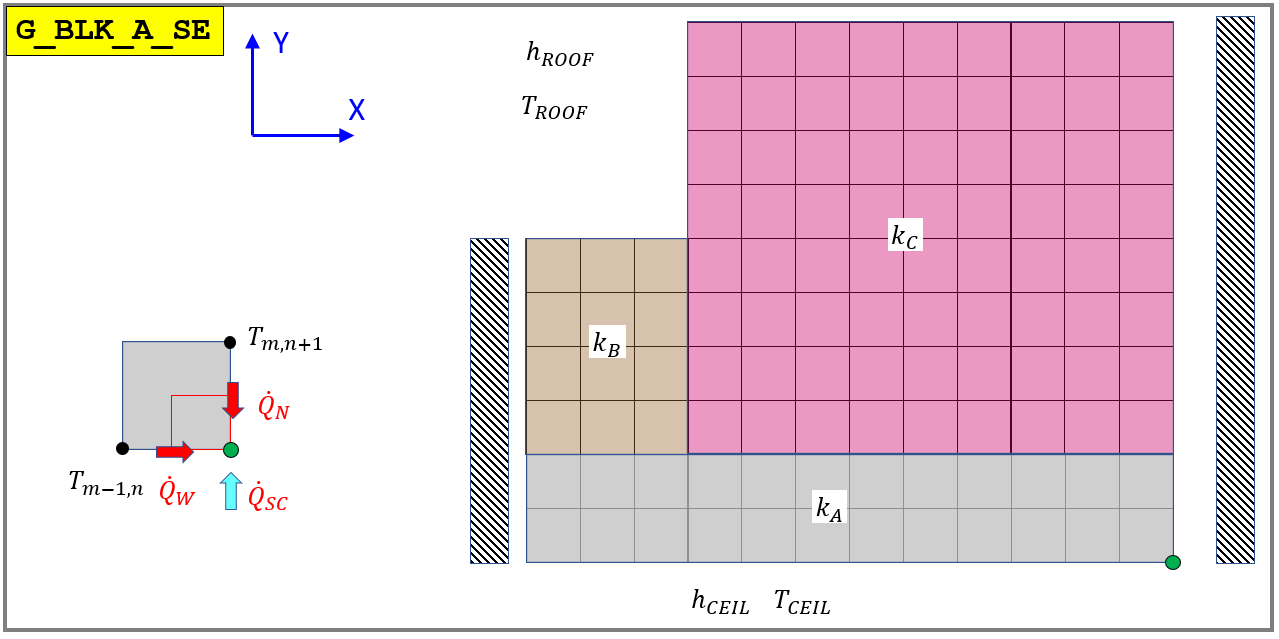

function [A, b, x]  = LOC_G_BLK_A_SE()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_HALF",  "E_0",    "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF", "S_0",     "E_0",    "W_HALF"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_A,      sym(0),   sym(0),     k_A);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc_BLK_A(A_cond, A_conv, k, d);    
end
%%%
%%
%

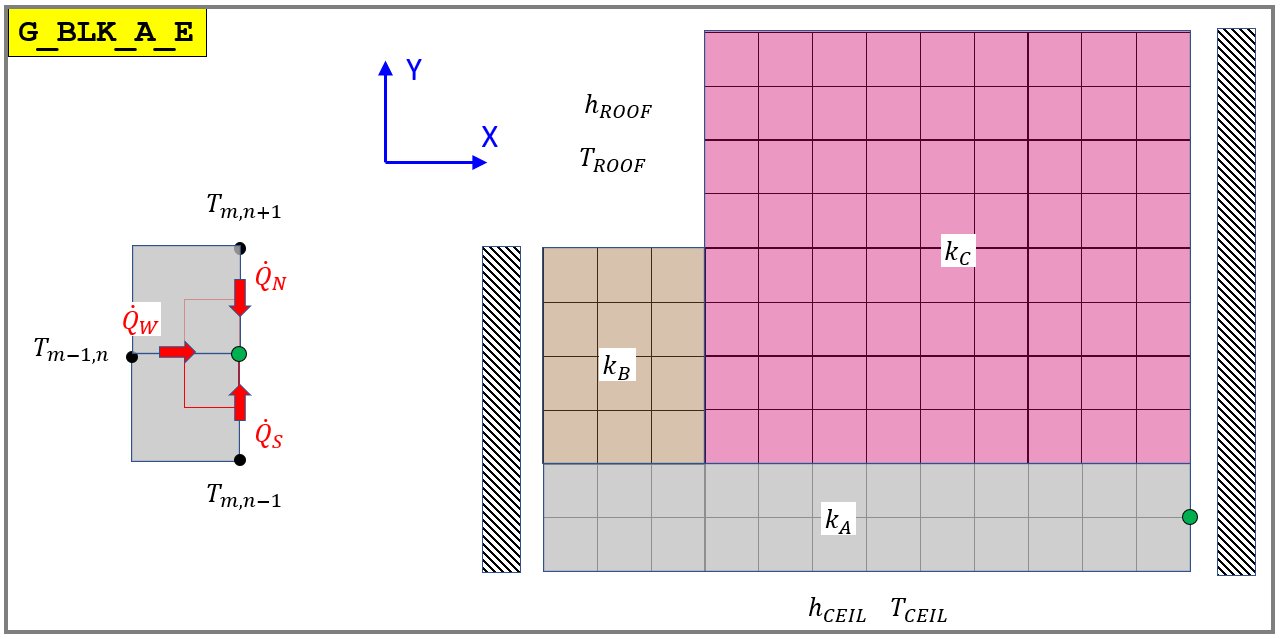

function [A, b, x]  = LOC_G_BLK_A_E()
  bh_symbol_DEFS                          %  xxxxxx    xxxxxx    xxxxxx  xxxxxx
  [A_NC, A_SC, A_EC, A_WC] = LOC_get_A_NSEW("N_0",    "S_0 ",    "E_0",    "W_0"); % Convection Areas
  [A_N,  A_S , A_E , A_W ] = LOC_get_A_NSEW("N_HALF", "S_HALF",  "E_0",    "W_FULL"); % CONDUCTION Areas
  [k_N , k_S , k_E , k_W ] =           deal( k_A,      k_A,      sym(0),     k_A);
    
  [d_N ,  d_S, d_E ,  d_W] = LOC_get_d_NSEW("N_FULL", "S_FULL", "E_FULL","W_FULL");
  
  d      = [d_N , d_S,  d_E , d_W ];
  k      = [k_N , k_S , k_E , k_W ];
  A_conv = [A_NC, A_SC, A_EC, A_WC];
  A_cond = [A_N,  A_S , A_E , A_W ];
  
  [A, b, x] = LOC_stenc_calc_BLK_A(A_cond, A_conv, k, d);    
end
%%%
%%
%

# **Utilities**

Specifying the **Area** of a FACE of a control surface

function [N_A, S_A, E_A, W_A] = LOC_get_A_NSEW(N,S,E,W)
    arguments
        N (1,1) string {mustBeMember(N, ["N_0","N_HALF","N_FULL"])}
        S (1,1) string {mustBeMember(S, ["S_0","S_HALF","S_FULL"])}
        E (1,1) string {mustBeMember(E, ["E_0","E_HALF","E_FULL"])}
        W (1,1) string {mustBeMember(W, ["W_0","W_HALF","W_FULL"])}    
    end
    
    bh_symbol_DEFS
    
    [N_A, S_A, E_A, W_A] = deal( sym(0),  sym(0),  sym(0),  sym(0) );
    
    switch N
        case "N_HALF"
                      N_A = Delta_X/2;
        case "N_FULL"
                      N_A = Delta_X;
    end
    
    switch S
        case "S_HALF"
                      S_A = Delta_X/2;
        case "S_FULL"
                      S_A = Delta_X;
    end        

    switch E
        case "E_HALF"
                      E_A = Delta_Y/2;
        case "E_FULL"
                      E_A = Delta_Y;
    end 
    
    switch W
        case "W_HALF"
                      W_A = Delta_Y/2;
        case "W_FULL"
                      W_A = Delta_Y;
    end            
end

xxx

Specifying the DISTANCE travelled by Q passing through  FACE N or S or E or W

function [N_d, S_d, E_d, W_d] = LOC_get_d_NSEW(N,S,E,W)
    arguments
        N (1,1) string {mustBeMember(N, ["N_0", "N_FULL"])}
        S (1,1) string {mustBeMember(S, ["S_0", "S_FULL"])}
        E (1,1) string {mustBeMember(E, ["E_0", "E_FULL"])}
        W (1,1) string {mustBeMember(W, ["W_0", "W_FULL"])}    
    end
    
    bh_symbol_DEFS
    
    [N_d, S_d, E_d, W_d] = deal( sym(0),  sym(0),  sym(0),  sym(0) );
    
    switch N
        case "N_FULL"
                      N_d = Delta_Y;
    end
    
    switch S
        case "S_FULL"
                      S_d = Delta_Y;
    end        

    switch E
        case "E_FULL"
                      E_d = Delta_X;
    end 
    
    switch W
        case "W_FULL"
                      W_d = Delta_X;
    end            
end

A list of Temperatures

function T_list = LOC_T_vars()

    bh_symbol_DEFS

    T_list = [T_mM1_nP1, T_m_nP1,  T_mP1_nP1, ...
              T_mM1_n,   T_m_n,    T_mP1_n, ...
              T_mM1_nM1, T_m_nM1,  T_mP1_nM1 ];

end

The Stencil calc for Blocks B and C

function [A, b, x] = LOC_stenc_calc(A_cond, A_conv, k, d)
  bh_symbol_DEFS                          
  
  [A_N,  A_S , A_E , A_W ] = deal(A_cond(1), A_cond(2), A_cond(3), A_cond(4) ); % CONDUCTION Areas  
  [A_NC, A_SC, A_EC, A_WC] = deal(A_conv(1), A_conv(2), A_conv(3), A_conv(4) ); % CONVECTION Areas
  [k_N , k_S , k_E , k_W ] = deal(     k(1),      k(2),      k(3),      k(4) ); % k
  [d_N , d_S,  d_E , d_W ] = deal(     d(1),      d(2),      d(3),      d(4) ); % d
  
  Q_NC = h_ROOF * A_NC * (T_ROOF - T_m_n);
  Q_SC = h_ROOF * A_SC * (T_ROOF - T_m_n);
  Q_EC = h_ROOF * A_EC * (T_ROOF - T_m_n);
  Q_WC = h_ROOF * A_WC * (T_ROOF - T_m_n);
  
  Q_N =     k_N * A_N * (T_NORTH - T_m_n) / d_N; 
  Q_S =     k_S * A_S * (T_SOUTH - T_m_n) / d_S; 
  Q_E =     k_E * A_E * (T_EAST  - T_m_n) / d_E; 
  Q_W =     k_W * A_W * (T_WEST  - T_m_n) / d_W;  
  
  Q_eq = 0 == (Q_NC + Q_SC + Q_EC + Q_WC +    Q_N + Q_S + Q_E + Q_W);
  
      x  = LOC_T_vars;
  [A, b] = equationsToMatrix(Q_eq, x);
    
end

The Stencil calc for Block A

function [A, b, x] = LOC_stenc_calc_BLK_A(A_cond, A_conv, k, d)
  bh_symbol_DEFS                          
  
  [A_N,  A_S , A_E , A_W ] = deal(A_cond(1), A_cond(2), A_cond(3), A_cond(4) ); % CONDUCTION Areas  
  [A_NC, A_SC, A_EC, A_WC] = deal(A_conv(1), A_conv(2), A_conv(3), A_conv(4) ); % CONVECTION Areas
  [k_N , k_S , k_E , k_W ] = deal(     k(1),      k(2),      k(3),      k(4) ); % k
  [d_N , d_S,  d_E , d_W ] = deal(     d(1),      d(2),      d(3),      d(4) ); % d
  
  Q_NC = h_CEIL * A_NC * (T_CEIL - T_m_n);
  Q_SC = h_CEIL * A_SC * (T_CEIL - T_m_n);
  Q_EC = h_CEIL * A_EC * (T_CEIL - T_m_n);
  Q_WC = h_CEIL * A_WC * (T_CEIL - T_m_n);
  
  Q_N =     k_N * A_N * (T_NORTH - T_m_n) / d_N; 
  Q_S =     k_S * A_S * (T_SOUTH - T_m_n) / d_S; 
  Q_E =     k_E * A_E * (T_EAST  - T_m_n) / d_E; 
  Q_W =     k_W * A_W * (T_WEST  - T_m_n) / d_W;  
  
  Q_eq = 0 == (Q_NC + Q_SC + Q_EC + Q_WC +    Q_N + Q_S + Q_E + Q_W);
  
      x  = LOC_T_vars;
  [A, b] = equationsToMatrix(Q_eq, x);
    
end